# TD MSD3 2019-20

## Exo 7. Hollow cylinder

### Statement of the exercise

A Steel hollow cylinder is disposed around a plain copper cylinder. A perfectly rigid plate is put on the top of both in order to apply a uniform axial load of 250 kN as shown in the figure. The cross section area of the steel part is  $A_S =18\;{\textrm{cm}}^2 \;$and of the copper is $A_C =60\;{\textrm{cm}}^2$. Before applying the load, both cylinders are of identical length.

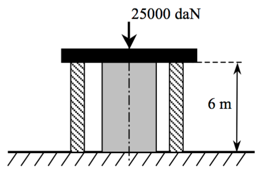 

1. Calculate the stresses in both cylinders. For this purpose write the “shape” of both tensor matrices, the Young’s equation and the boundary equations.

Calculate the required temperature rise of the whole system so that the load is only applied on the copper cylinder.  

The Young modulus and thermal expansion coefficients of steel and copper are : $E_S =210\;\textrm{GPa}$ ;$\alpha_S =11\times {10}^{-6} \;{\mathrm{K}}^{-1}$ ; $E_C =110\;\textrm{GPa}$ and  $\alpha_C =17\times {10}^{-6} \;{\mathrm{K}}^{-1}$.

### Solution of the exercise

#### Question 1

Let's name the load axis $x_1$, owing to the symmetry, both tensors are similar and pure compression loading, which means that the axis $x_2$ and $x_3$ are equivalent. If both cyclinders are submitted to some load, then the matrices are :


$$\bar{\bar{\sigma_S } } =\left\lbrack \begin{array}{ccc}\sigma_S  & 0 & 0\\0 & 0 & 0\\0 & 0 & 0\end{array}\right\rbrack$$

$$\bar{\bar{\varepsilon_S } } =\left\lbrack \begin{array}{ccc}\varepsilon_{1S}  &0 & 0\\0 & \varepsilon_{2S}  & 0\;\\0 & 0 & \varepsilon_{2S} \end{array}\right\rbrack$$

$$\bar{\bar{\sigma_C } } =\left\lbrack \begin{array}{ccc}\sigma_C  & 0 & 0\\0 & 0 & 0\\0 & 0 & 0\end{array}\right\rbrack$$
 
$$\bar{\bar{\varepsilon_C } }=\left\lbrack\begin{array}{ccc}\varepsilon_{1C}  & 0 & 0\\0 & \varepsilon_{2C}  & 0\\0 & 0 & \varepsilon_{2C} \end{array}\right\rbrack$$
  

One can write the Young's equations for direction $x_1$ for both materials :

    $\left\{ \begin{array}{ccc} \epsilon_{1C} =\frac{1}{E_C }\sigma_C +\alpha_C \Delta T \\ \epsilon_{1S} =\frac{1}{E_S }\sigma_S +\alpha_S \Delta T \end{array}$    (1)

When the plate is applied on both materials, the total force is decomposed into the force on copper and the force on steal, which means that one can write $F=F_C+F_S$, and since the load on a given cylinder is equal to the product of the stress by is cross-section area, which can be written considering the sign : 

    $-F=\sigma_CS_C+\sigma_SS_S$     (2)

system (1) and (2) represent the equation of that system in the general case.

The limiting case for which the load is only supported by the copper, is when the strain in both materials are identical : $\epsilon_{1S}=\epsilon_{1C}$, when the stress in the steal is nil : $\sigma_S=0$, and when the stress in the copper is simply $\sigma_C=-\frac{F}{S_C}$

Therefore : $\frac{1}{E_C }\sigma_C +\alpha_C \Delta T=\alpha_S \Delta T\iff \Delta T=\frac{-F}{E_C S_C \left(\alpha_S -\alpha_C\right)}$ 

Sc=60e-4;a_c=17e-6;a_s=11e-6;Ec=110e9;F=250e3;
DT=-F/(Ec*Sc*(a_s-a_c)); fprintf('DT = %1.1f °C',DT)

DT = 63.1 °C


$$\epsilon_{2C}=\frac{1}{E_C}(-\nu\sigma_{1C})+\alpha_C\Delta T$$


## Exo 8. Three layers plate

### Statement of the exercise

Consider the following square plate made of one layer of copper surrounded by two layers of steel. The copper thickness is $t_c =3\;\textrm{mm}$ and that of each layer of steel is $t_s =0\ldotp 5\;\textrm{mm}$. A circle of diameter $d=50\;\textrm{cm}$ is drawn on the upper surface. 

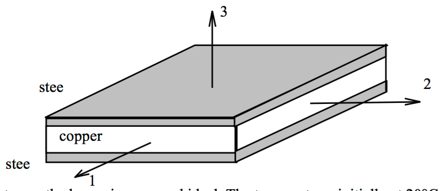

1. The boundary between the layers is supposed ideal. The temperature, initially at $T_i=20^\circ C$ is raised to $T_f=80^\circ C$.  Calculate the stresses tensors in the different plates.

2. The device is cooled back to $T_i=20^\circ C$ and a force of $F=10\,\mathrm{kN}$ is uniformly applied along direction $x_1$. Calculate the strain tensors in steel and copper. What is the final shape of the circle ? Give its final dimensions.

3. Calculate the energy stored in the device in the loading case of question 2.

$E_s=210\,\mathrm{GPa}$; $E_c=110\,\mathrm{GPa}$; $\alpha_s=14\times10^{-6}\,\mathrm{K^{-1}}$; $\alpha_c=20\times10^{-6}\,\mathrm{K^{-1}}$; $\nu_s=\nu_c=0.3$

### **Solution of the exercise**

#### **Question 1**

Owing to the shape symmetry and the loading, and that the boundary is ideal between the plates, we assume that the $(x_1,x_2,x_3)$ axis system is principal.

When we apply the temperature variation, owing to the thermal expansion, the two materials aim to expand and they do not have the same thermal expansion coefficient (cf figure 1 below on the left). They are not free to expand along $x_1$ and $x_2$ that are equivalent and they must expand to the same final length (Figure 1 on the right). This implies that there are stresses along $x_1$ and $x_2$ for both materials. Furthermore, owing to the symmetry and to the fact that their Poisson coefficient are identical, in each material $\sigma_1=\sigma_2$. On the contrary they are free to expend along $x_3$, which implied that $\sigma_3=0$.

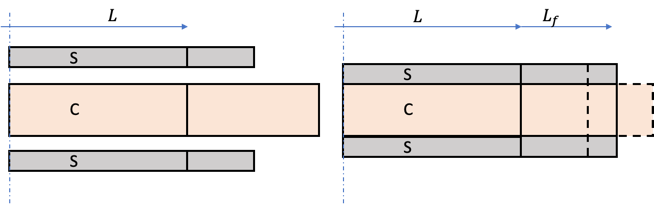

**Figure 1 **: schematic drawing of the expension along $x_1$ or $x_2$ if the materials were free to expand (on the left), and the real situation on the right where they are not free and must expand the same.

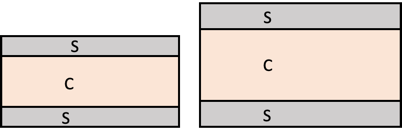

**Figure 2** : schematic representation of the expansion along $x_3$ where the plates can expand freely.

 The shapes of the tensors are :


$$\bar{\bar{\sigma_s } } =\left\lbrack \begin{array}{ccc}\sigma_{1s}  & 0 & 0\\0 &\sigma_{1s}  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_s } } =\left\lbrack \begin{array}{ccc}\epsilon_{1s}  & 0 & 0\\0 &\epsilon_{1s}  & 0\\0 & 0 & \epsilon_{3S}\end{array}\right\rbrack$$
   
$$\bar{\bar{\sigma_c } } =\left\lbrack \begin{array}{ccc}\sigma_{1c}  & 0 & 0\\0 &\sigma_{1c}  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_c } } =\left\lbrack \begin{array}{ccc}\epsilon_{1c}  & 0 & 0\\0 &\epsilon_{1c}  & 0\\0 & 0 & \epsilon_{3C}\end{array}\right\rbrack$$


Directions 1 and 2 are identical since we have the same Poissson ratio.

Young's equations in both materials are :

$\left\{\begin{array}{ccc}\epsilon_{1s}=\frac{(1-\nu_s)}{E_s}\sigma_{1s}+\alpha_s\Delta T\\\epsilon_{1c}=\frac{(1-\nu_c)}{E_c}\sigma_{1c}+\alpha_c\Delta T\end{array}$    (1) +(2)

Since the expansions are identical, one can write : $\epsilon_{1s}=\epsilon_{1c}$  (3)

The last equation is the force equilibrium equation. Along $x_1$ or $x_2$, the sum of the forces in each material must equal the surrounding force, which in that case is nil. Figure 2 shows that   the steal parts have actually a larger size length than the equilibium one it would have when expanding freely. Therefore,each steal part is submitted to a tensile force $f_S>0$. On the contrary the copper is sumitted to a force $f_C<0$. The equation can be written as :$f_C+2f_S=F_{ext}=0$. Replacing the stress and cross-section area in these equations leads to the fourth equation :

$2\sigma_{1s}S_s+\sigma_{1c}S_c=0$    (4)

4 unknowns and four equations, the system can be solved.

clear all
syms  nu e1s e1c s1s s1c Es Ec as ac DT Ss Sc
A1=e1s-e1c;
A2=e1s-((1-nu)*s1s)/Es-as*DT;
A3=e1c-((1-nu)*s1c)/Ec-ac*DT;
A4=2*s1s*Ss+s1c*Sc;
[A,B]=equationsToMatrix([A1,A2,A3,A4], [s1s,s1c,e1s,e1c])

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & -1\\ \frac{\nu -1}{\mathrm{Es}} & 0 & 1 & 0\\ 0 & \frac{\nu -1}{\mathrm{Ec}} & 0 & 1\\ 2\,\mathrm{Ss} & \mathrm{Sc} & 0 & 0 \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ \mathrm{DT}\,\mathrm{as}\\ \mathrm{DT}\,\mathrm{ac}\\ 0 \end{array}\right)$$

K=linsolve(A,B)

$$K = \begin{array}{l} \left(\begin{array}{c} -\frac{\mathrm{DT}\,\mathrm{Es}\,\left(\mathrm{Ec}\,\mathrm{Sc}\,\mathrm{ac}-\mathrm{Ec}\,\mathrm{Sc}\,\mathrm{as}\right)}{\left(\mathrm{Ec}\,\mathrm{Sc}+2\,\mathrm{Es}\,\mathrm{Ss}\right)\,\left(\nu -1\right)}\\ \frac{2\,\mathrm{DT}\,\mathrm{Es}\,\mathrm{Ss}\,\left(\mathrm{Ec}\,\mathrm{ac}-\mathrm{Ec}\,\mathrm{as}\right)}{\left(\mathrm{Ec}\,\mathrm{Sc}+2\,\mathrm{Es}\,\mathrm{Ss}\right)\,\left(\nu -1\right)}\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{DT}\,\left(\mathrm{Ec}\,\mathrm{Sc}\,\mathrm{ac}+2\,\mathrm{Es}\,\mathrm{Ss}\,\mathrm{as}\right)}{\mathrm{Ec}\,\mathrm{Sc}+2\,\mathrm{Es}\,\mathrm{Ss}} \end{array}$$

nu=0.3; Es=210e9; Ec=110e9; as=14e-6; ac=20e-6; DT=60;Ss=0.5e-3;Sc=3e-3;
fprintf('s1s = %1.1f MPa',eval(K(1))/1e6)

s1s = 66.0 MPa

fprintf('s1c = %1.1f MPa',eval(K(2))/1e6)

s1c = -22.0 MPa

fprintf('e1s = %1.2e ',eval(K(3)))

e1s = 1.06e-03 

So the result is compatible since $\sigma_{1S}>0$ and $\sigma_{1C}<0$.

#### Question 2.

**Simplified method when **$\nu_s=\nu_c$

When we add an external force $F$ to the plate, the boundary conditions are changed. It is obvious that we have non nil stresses $\sigma_{1s}$ and $\sigma_{1c}$ along $x_1$. However the question of having non nil stresses $\sigma_{2s}$ and $\sigma_{2c}$ anlong $x_2$ is less obvious. If there are, this is due to the fact that applying the force along $x_1$ induces a contraction along $x_2$ for both material, that are not free to expand. This would lead to the tensor shapes :


$$\bar{\bar{\sigma_s } } =\left\lbrack \begin{array}{ccc}\sigma_{1s}  & 0 & 0\\0 &\sigma_{2s}  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_s } } =\left\lbrack \begin{array}{ccc}\epsilon_{1s}  & 0 & 0\\0 &\epsilon_{2s}  & 0\\0 & 0 &\epsilon_{3s} \end{array}\right\rbrack$$
   
$$\bar{\bar{\sigma_c } } =\left\lbrack \begin{array}{ccc}\sigma_{1c}  & 0 & 0\\0 &\sigma_{2c}  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_c } } =\left\lbrack \begin{array}{ccc}\epsilon_{1c}  & 0 & 0\\0 &\epsilon_{2c}  & 0\\0 & 0 &\epsilon_{3c} \end{array}\right\rbrack$$


and just as before we just have to write the equations, the boundaries and solve the equations. 

However, before doing this one can investigate in more detail this questions of stresses along $x_2$. When applying the load along $x_1$, both materials are not free to expand, therefore one can write : $\epsilon_{1s}=\epsilon_{1c}$. Since each material is submitted to a tensile load, they exhibit a contraction strain $\epsilon_{1s}=-\frac{\epsilon_{2s}}{\nu_s}$ and $\epsilon_{1c}=-\frac{\epsilon_{2c}}{\nu_c}$. This shows that when the Poisson ratios of both materials are identical, $\nu_s=\nu_c=\nu$,  we have $\epsilon_{2s}=\epsilon_{2c}$, which means that both materials are at equilibrium and there is no stress along $x_2$ : $\sigma_{2s}=\sigma_{2c}=0$.

In this exercices we assume that both materials exhibit the same Poisson ratio, so that the shapes of the tensors are the following :


$$\bar{\bar{\sigma_s } } =\left\lbrack \begin{array}{ccc}\sigma_{1s}  & 0 & 0\\0 &0  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_s } } =\left\lbrack \begin{array}{ccc}\epsilon_{1s}  & 0 & 0\\0 &\epsilon_{2s}  & 0\\0 & 0 &\epsilon_{3s} \end{array}\right\rbrack$$
   
$$\bar{\bar{\sigma_c } } =\left\lbrack \begin{array}{ccc}\sigma_{1c}  & 0 & 0\\0 &0  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_c } } =\left\lbrack \begin{array}{ccc}\epsilon_{1c}  & 0 & 0\\0 &\epsilon_{2c}  & 0\\0 & 0 &\epsilon_{3c} \end{array}\right\rbrack$$


with $\epsilon_{2s}=\epsilon_{2c}$.

The equations are :

    $\left\{\begin{array}{ccc}\epsilon_{1s}=\frac{(1-\nu_s)}{E_s}\sigma_{1s}+\alpha_s\Delta T\\\epsilon_{1c}=\frac{(1-\nu_c)}{E_c}\sigma_{1c}+\alpha_c\Delta T\end{array}$    (1) +(2)

    $\epsilon_{1s}=\epsilon_{1c}$  (3)

    $2\sigma_{1s}S_s+\sigma_{1c}S_c=F$    (4)

This can be solved as in the question (1)

clear all
syms  nu e1s e1c s1s s1c Es Ec as ac DT Ss Sc F
A1=e1s-e1c;
A2=e1s-((1-nu)*s1s)/Es-as*DT;  % we keep DT and its value to 0
A3=e1c-((1-nu)*s1c)/Ec-ac*DT;
A4=2*s1s*Ss+s1c*Sc-F;
[A,B]=equationsToMatrix([A1,A2,A3,A4], [s1s,s1c,e1s,e1c])

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & -1\\ \frac{\nu -1}{\mathrm{Es}} & 0 & 1 & 0\\ 0 & \frac{\nu -1}{\mathrm{Ec}} & 0 & 1\\ 2\,\mathrm{Ss} & \mathrm{Sc} & 0 & 0 \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ \mathrm{DT}\,\mathrm{as}\\ \mathrm{DT}\,\mathrm{ac}\\ F \end{array}\right)$$

K=linsolve(A,B)

$$K = \begin{array}{l} \left(\begin{array}{c} -\frac{\mathrm{Es}\,F-\mathrm{Es}\,F\,\nu +\mathrm{DT}\,\mathrm{Ec}\,\mathrm{Es}\,\mathrm{Sc}\,\mathrm{ac}-\mathrm{DT}\,\mathrm{Ec}\,\mathrm{Es}\,\mathrm{Sc}\,\mathrm{as}}{\left(\mathrm{Ec}\,\mathrm{Sc}+2\,\mathrm{Es}\,\mathrm{Ss}\right)\,\left(\nu -1\right)}\\ -\frac{\mathrm{Ec}\,F-\mathrm{Ec}\,F\,\nu -2\,\mathrm{DT}\,\mathrm{Ec}\,\mathrm{Es}\,\mathrm{Ss}\,\mathrm{ac}+2\,\mathrm{DT}\,\mathrm{Ec}\,\mathrm{Es}\,\mathrm{Ss}\,\mathrm{as}}{\left(\mathrm{Ec}\,\mathrm{Sc}+2\,\mathrm{Es}\,\mathrm{Ss}\right)\,\left(\nu -1\right)}\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{F-F\,\nu +\mathrm{DT}\,\mathrm{Ec}\,\mathrm{Sc}\,\mathrm{ac}+2\,\mathrm{DT}\,\mathrm{Es}\,\mathrm{Ss}\,\mathrm{as}}{\mathrm{Ec}\,\mathrm{Sc}+2\,\mathrm{Es}\,\mathrm{Ss}} \end{array}$$

nu=0.3; Es=210e9; Ec=110e9; as=14e-6; ac=20e-6; DT=0;Ss=0.5e-3;Sc=3e-3; F=10e3;
fprintf('s1s = %1.1f MPa',eval(K(1))/1e6)

s1s = 3.9 MPa

fprintf('s1c = %1.1f MPa',eval(K(2))/1e6)

s1c = 2.0 MPa

This time both materials are submitted to tensile stresses but the values are different. 

**Alternative general solution **:

If we the Poisson ratio were different or we simply do not want to specify the hypotheses goven above, then we have to assume that the tensor shapes are :


$$\bar{\bar{\sigma_s } } =\left\lbrack \begin{array}{ccc}\sigma_{1s}  & 0 & 0\\0 &\sigma_{2s}  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_s } } =\left\lbrack \begin{array}{ccc}\epsilon_{1s}  & 0 & 0\\0 &\epsilon_{2s}  & 0\\0 & 0 &\epsilon_{3s} \end{array}\right\rbrack$$
   
$$\bar{\bar{\sigma_c } } =\left\lbrack \begin{array}{ccc}\sigma_{1c}  & 0 & 0\\0 &\sigma_{2c}  & 0\\0 & 0 & 0\end{array}\right\rbrack$$
   
$$\bar{\bar{\epsilon_c } } =\left\lbrack \begin{array}{ccc}\epsilon_{1c}  & 0 & 0\\0 &\epsilon_{2c}  & 0\\0 & 0 &\epsilon_{3c} \end{array}\right\rbrack$$


The number of equations is larger, but idea is the same 

$\left\{\begin{array}{ccc}\varepsilon_{1s} =\frac{1}{E_s }\left(\sigma_{1s} -\nu \sigma_{2s} \right)+\alpha_s \Delta T\\\varepsilon_{2s} =\frac{1}{E_s }\left(\sigma_{2s} -\nu \sigma_{1s} \right)+\alpha_s \Delta T\end{array}$    (1) + (2)

$\left\{\begin{array}{ccc}\varepsilon_{1c} =\frac{1}{E_c }\left(\sigma_{1c} -\nu \sigma_{2c} \right)+\alpha_c \Delta T\\\varepsilon_{2c} =\frac{1}{E_c }\left(\sigma_{2c} -\nu \sigma_{1c} \right)+\alpha_c \Delta T\end{array}$    (3) + (4)

$\left\{\begin{array}{ccc}\epsilon_{1s}=\epsilon_{1c}\\ \epsilon_{2s}=\epsilon_{2c}\end{array}$    (5) + (6)

$\left\{\begin{array}{cc} F=2\sigma_{1s} S_s +\sigma_{1c} S_c\\ 0=2\sigma_{2s} S_s +\sigma_{2c} S_c\end{array}$ (7) + (9)

We indeed have a system of 8 equations and 8 unknowns that can be solved

clear all
syms  nus nuc s1s s2s e1s e2s s1c s2c e1c e2c Es Ec as ac DT Ss Sc F
A1=e1s-1/Es*(s1s-nus*s2s)-as*DT;
A2=e2s-1/Es*(s2s-nus*s1s)-as*DT;
A3=e1c-1/Ec*(s1c-nuc*s2c)-ac*DT;
A4=e2c-1/Ec*(s2c-nuc*s1c)-ac*DT;
A5=e1s-e1c;
A6=e2s-e2c;
A7=F-2*s1s*Ss-s1c*Sc;
A8=2*s2s*Ss+s2c*Sc;
[A,B]=equationsToMatrix([A1,A2,A3,A4,A5,A6,A7,A8], [s1s,s2s,s1c,s2c,...
    e1s,e2s,e1c,e2c]);
K=linsolve(A,B);
nus=0.3; nuc=0.3; Es=210e9; Ec=110e9; as=14e-6; ac=20e-6; DT=0; Ss=0.5e-3;Sc=3e-3; F=10e3;

fprintf('s1s = %1.1f MPa',eval(K(1))/1e6)

s1s = 3.9 MPa

fprintf('s2s = %1.1f MPa',eval(K(2))/1e6)

s2s = 0.0 MPa

fprintf('s1c = %1.1f MPa',eval(K(3))/1e6)

s1c = 2.0 MPa

fprintf('e1s = %1.1e',eval(K(5)))

e1s = 1.9e-05

fprintf('e1c = %1.1e',eval(K(7)))

e1c = 1.9e-05

fprintf('e2s = %1.1e',eval(K(6)))

e2s = -5.6e-06

fprintf('e2c = %1.1e',eval(K(8)))

e2c = -5.6e-06


sig_c=[K(3) 0 0;0 0 0; 0 0 0]
eps_c=[K(7) 0 0; 0 0 0;0 0 0]
Wv_c=sum(sum(sig_c.*eps_c))

So we indeed find the same result as before, i.e. $\sigma_{2s}=\sigma_{2c}=0$

#### Question 3

We assume we know the stress tensors in copper and steel. The volumic energies in each materials are therefore : $W_c^{vol}=\frac{1}{2}\tilde\sigma_c:\tilde\epsilon_c$ and $W_s^{vol}=\frac{1}{2}\tilde\sigma_s:\tilde\epsilon_s$

The total energy is therefore : 


$$2\int_{V_s}W_s^{vol}(V)dV+\int_{V_c}W_c^{vol}(V)dV=2W_s^{vol}L^2t_s+W_c^{vol}L^2t_c$$


%syms ts tc % thickness of the materials
s1s=eval(K(1)); s1c=eval(K(3)); s2s=eval(K(2)); s2c=eval(K(4));
ss=[s1s 0 0;0 s2s 0;0 0 0]; sc=[s1c 0 0;0 s2c 0;0 0 0];
es=(1+nus)/Es*ss-nus/Es*trace(ss)*eye(3);
ec=(1+nuc)/Ec*sc-nuc/Ec*trace(sc)*eye(3);
Ws_v=1/2*sum(sum(ss.*es));
Wc_v=1/2*sum(sum(sc.*ec));
L=1; ts=0.5e-3; tc=3e-3;
W=2*Ws_v*L^2*ts+Wc_v*L^2*tc

W = 0.0926